# Simulation of the gaussian beam through an optical fiber

Every parameter in this program is in SI units.

## Parameters

Physical parameters

l = 1000e-6; % Wavelength
Ns = 1.45; % Silica idex
Na = 1; % Air index (for later)

Laser parameters

On = 4e-1; % Numerical aperture
w0 = 3e-6; % Waist
M = sqrt(pi*w0^2*On/l); % Square root of the beam-quality factor
zr = w0/On; % Rayleigh distance

Fiber parameters

R = 62.5e-6; % Curvature radius
zi = -20e-6 ; % Position of the interface
zmax = zi + R; % Radius of the fiber

Numerical parameters

res = 1.5e6; % Numerical resolution 
x = linspace(-2*w0,2*w0,res); % Transverse coordinates
z = linspace(-2*zmax,2*zmax,R*res); % Propagation coordinates

## Simulations

Inline function to compute the Complex beam parameter

q = @(z) z + 1i*zr;

Inline function to compute the Gaussian beam width

w = @(z) w0*sqrt(1+(z/z(1,1)^2));

Matrix representation of the picture

P = [];

W = NaN(size(z)); % Matrix containing all the values for the radius of the beam

Q = NaN(size(z)); % Matrix containing all the complex beam parameters value
Q(1,1) = feval(q,z(1,1)); % Initialization of the first value

Index exceeds matrix dimensions.


passed = false; % Boolean checking that we only pass the interface once (Numerical simulation artefact)

A = 1;

for idx = 2:numel(z)
    zTemp = z(idx); % Retrieving value corresponding to the index (Parallelization artefact)
    
    % Interface case
    if zTemp >= zi && ~passed % <- Not passed
        % Air/Silica curved interface ABCD matrix
        B = 0;
        C = (Na-Ns)/(R*Ns);
        D = Na/Ns;
        Mas = [A,B;
            C,D];
        
        % Computation of the simulated output complex beam parameter after the interface
        Q2 = Mas*[Q(idx-1);1];
        Q(1,idx) = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
        passed = true;
        
%         Q2 = Masf*[Q(idx-1);1];
%         Q(1,idx) = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
%         passed = true;
        
    else
        % Free space matrix (air or silica)
        B = zTemp - z(idx-1); % Position of the considered point (variable)
        C = 0;
        D = 1;
        Mp = [A,B;
            C,D];
        
        % Computation of the simulated output complex beam parameter
        Q2 = Mp*[Q(idx-1);1];
        Q(1,idx) = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
    end
    
    W(1,idx) = feval(w,zTemp); % Keeping the current waist to find the minimum at the end
    
%     % Computation of the real radius
%     R = 1/(1/Q(1,idx)+1i*l*M^2/(pi*Ns*W(1,idx)^2));
%     Pr = [Pr,R];
     
    % Computation of the intensity on the zTemp-plane
    U = @(x,zTemp) 1/Q(1,idx)^(M^2/2)... <- For readability
        .*(exp(-(1i*pi*x.^2)/(l*Q(1,idx)))...
        .*polyval(hermitePoly(M^2),sqrt(2)*(M.*x)/(W(1,idx))));
    I = abs(feval(U,x,zTemp).^2);
    P = vertcat(P,I);
end

## Plotting

Intensity

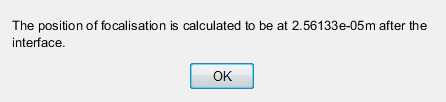

imagesc(P'); colormap(hot); colorbar;
ax = gca;

pI = find(z >= zi); % Retreving the position of the interface in the matrix
[~,pF] = max(var(P,0,2)); % Retreving the position of focalisation in the matrix

msgbox(sprintf('The position of focalisation is calculated to be at %gm after the interface.',... <- Displaying the position in a message box
                ((z(1,end)-z(1,1))*(pF-pI(1,1))/res))); 

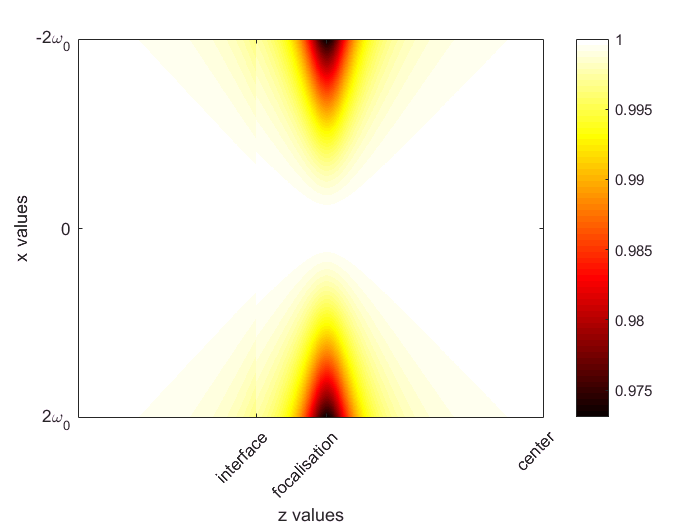


ax.XTickLabelRotation = 45;
xlabel('z values'); ax.XTick = [0 pI(1,1) pF res-1]; ax.XTickLabel = {'0','interface','focalisation','center'};
ylabel('x values'); ax.YTick = [1 res/2 res]; ax.YTickLabel = {'-2\omega_0','0','2\omega_0'};